clear; clc; close all;

%% =========================
% Zero joint position
% All joint angles are in radians
%% =========================
q = [0 0 0 0 0];

%% =========================
% Robot dimensions
%% =========================
b  = 2.5;
L1 = 5;
L2 = 22;
L3 = 18;
L4 = 10;

%% =========================
% Chessboard parameters
% Base at x = 0, y = 0
% Chessboard spans:
%   x in [0, 30]
%   y in [-15, 15]
%% =========================
board_size   = 40;
board_x_min  = 8;
board_y_min  = -board_size/2;
board_z      = 0;
num_squares  = 8;

piece_height = 9.5;
lift_height  = 2 * piece_height;



%% =========================
% Joint ranges
%% =========================
% q1_range = −180° to 180°
% q2_range = −90° to −10° and 10° to 90°
% q3_range = −120° to −10° and 10° to 120°
% q4_range = −120° to −10° and 10° to 120°
% q5_range = −180° to 180°




%% =========================
% Standard DH table
% Each row = [a_{i-1}, alpha_{i-1}, d_i, theta_i]
%% =========================
DH_table = [ ...
   -b,   pi/2,   L1,      q(1);
    L2,    0,     0,      q(2) + pi/2;
    L3,    0,     0,      q(3);
     0,   -pi/2,  0,      q(4) - pi/2;
     0,    0,    L4,      q(5)
];

%% =========================
% Forward kinematics
%% =========================
n = size(DH_table,1);

T = eye(4);                  % cumulative transform
origins = zeros(3,n+1);      % O0 to On
origins(:,1) = [0;0;0];      % base origin

T_all = cell(1,n);           % store cumulative transforms

for i = 1:n
    a     = DH_table(i,1);
    alpha = DH_table(i,2);
    d     = DH_table(i,3);
    theta = DH_table(i,4);

    A_i = DH_std(a, alpha, d, theta);   % A_i = T_{i-1}^{i}
    T = T * A_i;                        % cumulative transform

    T_all{i} = T;
    origins(:,i+1) = T(1:3,4);
end

%% =========================
% Display final end-effector transform
%% =========================
disp('Final transformation matrix T_0^E at zero position:');

Final transformation matrix T_0^E at zero position:


disp(T);

    1.0000         0         0   -2.5000
         0    1.0000         0    0.0000
         0         0    1.0000   55.0000
         0         0         0    1.0000



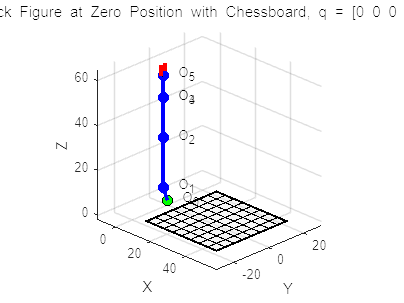


%% =========================
% Plot stick figure
%% =========================
figure;
hold on;

% -------------------------
% Draw chessboard plane
% -------------------------
x1 = board_x_min;
x2 = board_x_min + board_size;
y1 = board_y_min;
y2 = board_y_min + board_size;
z0 = board_z;

% Draw board surface (light gray, slightly transparent)
fill3([x1 x2 x2 x1], ...
      [y1 y1 y2 y2], ...
      [z0 z0 z0 z0], ...
      [0.9 0.9 0.9], ...
      'FaceAlpha', 0.35, ...
      'EdgeColor', 'k', ...
      'LineWidth', 1.5);

% Draw 8x8 grid lines
square_size = board_size / num_squares;

for k = 0:num_squares
    % lines parallel to Y
    xg = x1 + k * square_size;
    plot3([xg xg], [y1 y2], [z0 z0], 'k', 'LineWidth', 0.8);

    % lines parallel to X
    yg = y1 + k * square_size;
    plot3([x1 x2], [yg yg], [z0 z0], 'k', 'LineWidth', 0.8);
end

% -------------------------
% Plot robot arm (BLUE)
% -------------------------
plot3(origins(1,:), origins(2,:), origins(3,:), '-o', ...
      'Color', 'b', ...
      'LineWidth', 2.5, ...
      'MarkerSize', 6, ...
      'MarkerFaceColor', 'b');

grid on; 
axis equal;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Stick Figure at Zero Position with Chessboard, q = [0 0 0 0 0]^T');

for i = 1:(n+1)
    text(origins(1,i), origins(2,i), origins(3,i), sprintf('  O_%d', i-1));
end

%% =========================
% Draw gripper at Frame 5
% Opening along z5, separated along y5
%% =========================
T5 = T_all{5};   % transform of frame 5 wrt base

finger_length = 5;
finger_offset = 1;

% In frame 5:
% two fingers located at y5 = +1 and y5 = -1
% each finger extends along +z5 direction

p1_base_5 = [0;  finger_offset; 0; 1];
p1_tip_5  = [0;  finger_offset; finger_length; 1];

p2_base_5 = [0; -finger_offset; 0; 1];
p2_tip_5  = [0; -finger_offset; finger_length; 1];

% Transform to base frame
p1_base_0 = T5 * p1_base_5;
p1_tip_0  = T5 * p1_tip_5;

p2_base_0 = T5 * p2_base_5;
p2_tip_0  = T5 * p2_tip_5;

% Plot the two fingers (RED)
plot3([p1_base_0(1), p1_tip_0(1)], ...
      [p1_base_0(2), p1_tip_0(2)], ...
      [p1_base_0(3), p1_tip_0(3)], ...
      'r', 'LineWidth', 3);

plot3([p2_base_0(1), p2_tip_0(1)], ...
      [p2_base_0(2), p2_tip_0(2)], ...
      [p2_base_0(3), p2_tip_0(3)], ...
      'r', 'LineWidth', 3);

% Connect the two finger bases (BLACK)
plot3([p1_base_0(1), p2_base_0(1)], ...
      [p1_base_0(2), p2_base_0(2)], ...
      [p1_base_0(3), p2_base_0(3)], ...
      'k', 'LineWidth', 2);

%% =========================
% Highlight base point only (no text)
%% =========================
plot3(0, 0, 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

%% =========================
% Better view
%% =========================
view(45,25);

% Optional axis limits for better visibility
xlim([min(-10, x1-5), x2+10]);
ylim([y1-10, y2+10]);
zlim([min(-2, z0-2), max(origins(3,:))+10]);


%% =========================
% Standard DH function
%% =========================

function T = DH_std(a, alpha, d, theta)
% Standard DH transform using [a_{i-1}, alpha_{i-1}, d_i, theta_i]

T = [cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
     sin(theta),  cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
     0,           sin(alpha),             cos(alpha),            d;
     0,           0,                      0,                     1];
end